# MATLAB & Simulink workshop

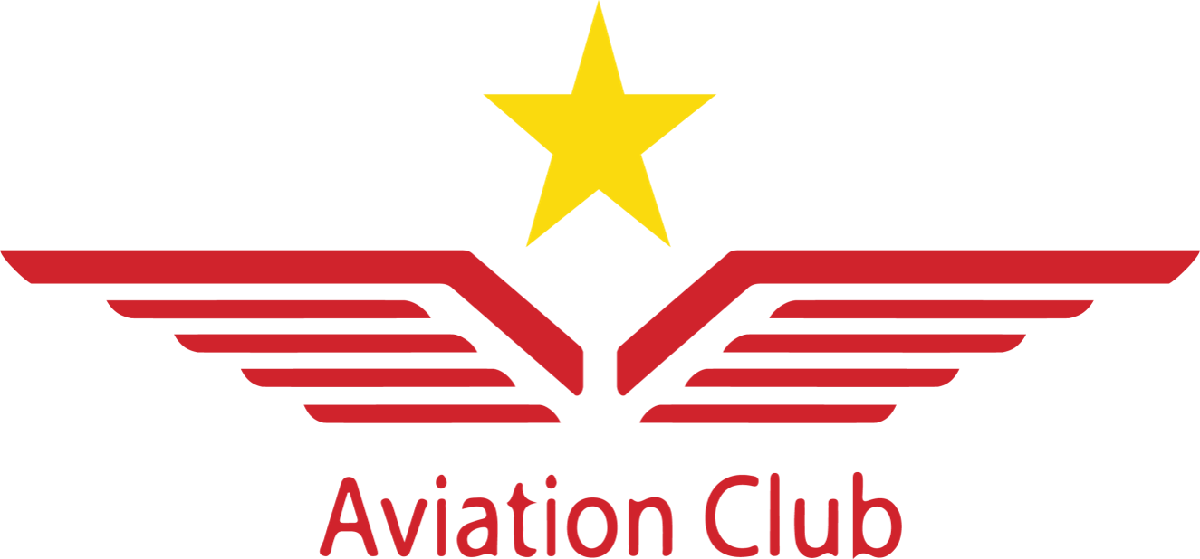

## Session 5: Data fitting

Before we start any script

clear
clc
close all  

Before digging deeper into data fitting let's discuss important topics

### Part 1: Error handling

error() function

x=5

x = 5

if(x<0)
    error('Negative numbers are not supported')
else
    disp('operation succesful')
end

operation succesful


assert()

x=[3 5];
assert(~isscalar(x),'meaningless to sum scalars')
y=sum(x);

try and catch

a=1;
try
    z=a/b;
catch err
    disp('division by zero is not allowed');
end

division by zero is not allowed


error message identifier

a=1;
try
    z=a/b;
catch err
    if strcmp(err.identifier,'MATLAB:UndefinedFunction')
        disp('b was missing, defining b now')
        b=1; 
    else
        rethrow(err)
    end
end

b was missing, defining b now


### Part 2: Files I/O

You can import data from csv file through readmatrix() or readtable()

x=readmatrix('LDR_calebration.csv')

x =     3.9100         0         0
   95.7500   22.0000    0.1075
  139.0000   36.0000    0.1760
  172.0400   61.0000    0.2981
  240.0000   94.0000    0.4594
  265.0000  108.0000    0.5279
  308.0000  135.0000    0.6598


y=readtable('LDR_calebration.csv')

y = 7×3 table
     Klux     ArduinoOutput     Volt  
    ______    _____________    _______

      3.91           0               0
     95.75          22         0.10753
       139          36         0.17595
    172.04          61         0.29814
       240          94         0.45943
       265         108         0.52786
       308         135         0.65982


Let's try the same for xlsx file

temp=readtable("Temp sensor.xlsx");
temp2=readmatrix("Temp sensor.xlsx")

temp2 =    30.0000    0.2340
   40.0000    0.2400
   50.0000    0.2590
   60.0000    0.2600
   70.0000    0.2700
   80.0000    0.3000


head(temp)

    Temp    Voltage
    ____    _______

     30      0.234 
     40       0.24 
     50      0.259 
     60       0.26 
     70       0.27 
     80        0.3 



temp2

temp2 =    30.0000    0.2340
   40.0000    0.2400
   50.0000    0.2590
   60.0000    0.2600
   70.0000    0.2700
   80.0000    0.3000


You can do that too from import data app

import_test

It is always better to use try and catch with file reading

try
    readtable('LDR calebration.csv')
catch
    disp('error couldn''t open file')
end

error couldn't open file


### Part 3: Data fitting

First thing we will do is extract some info from the data we read

clear
import_test
x=LDRcalebration.Klux;
y=LDRcalebration.Volt;

Then to fit the data we use polyfit()

line=polyfit(x,y,1)

line =     0.0022   -0.0732


plot(x,y,'ro-','LineWidth',2)
hold on
t=linspace(0,300,7);
y_fit=t.*line(1)+line(2)

y_fit =    -0.0732    0.0388    0.1508    0.2628    0.3748    0.4868    0.5988


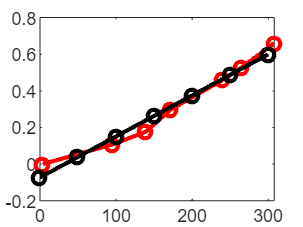

plot(t,y_fit,'ko-','LineWidth',2)

Instead of calculating it manually we can use polyval()

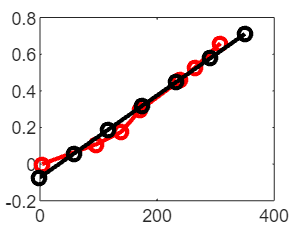

close all
t2=linspace(0,350,7);
y_fit2=polyval(line,t2);
plot(x,y,'ro-','LineWidth',2)
hold on
plot(t2,y_fit2,'ko-','LineWidth',2)

Try changing polynomial order

close all
curve_sqr=polyfit(x,y,2);
t3=linspace(0,350,7);
y_fit3=polyval(curve_sqr,t3)

y_fit3 =    -0.0102    0.0585    0.1551    0.2797    0.4321    0.6124    0.8207


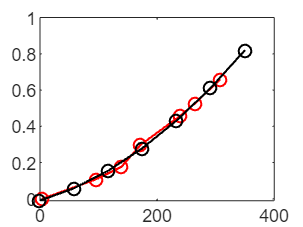

plot(x,y,'ro-','LineWidth',1)
hold on
plot(t3,y_fit3,'ko-','LineWidth',1)

We can do more complex fitting using fit() but we will use the MATLAB app

let's try generating random data

close all
x_train=linspace(0,300,50);
y_true=x_train.^2 .*10;
y_train=x_train.^2 .*10 +30000*randn(1,length(x_train))

y_train = 1.0e+05 *

   -0.4817    0.2022    0.6565    0.1961   -0.4023    0.0328   -0.0150    0.2986    0.3635    0.4253    0.2657    0.2738    0.3629    0.8895    0.1788    0.7812    1.0407    0.8875    1.3577    1.3318    1.2179    1.7015    1.7338    1.8600    1.9457    2.3612    1.9801    2.6131    2.7757    2.8789    3.5694    3.3820    4.0006    4.3748    4.2861    4.6752    5.0498    5.1073    5.5750    5.3226    6.3306    6.0043    6.0636    7.3462    7.2382    7.7253    7.8227    7.9741    7.7145    9.1879


y_val = 1.0e+06 *

    2.4914    2.5781    2.6816    2.7137    2.8226    2.9684    3.0429    3.0789    3.1450    3.2891    3.4092    3.5290    3.6028    3.6670    3.8120    3.8711    3.9823    4.0977    4.1881    4.3259    4.4174    4.5477    4.6556    4.7717    4.8849


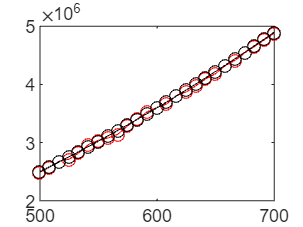

plot(x_train,y_train, '-or')
hold on
plot(x_train,y_true, '-ok')


Let's generate validation data

close all
x_val=linspace(500,700,25);
y_val=x_val.^2 .*10 +30000*randn(1,length(x_val))
plot(x_val,y_val,'-ro')
y_true2=x_val.^2 .*10;
hold on 
plot(x_val,y_true2,'-ok')

### Part 4: Signals processing

let's start by defining a signal

clc; clear; close all;
x=linspace(0,4*pi,100);
y=sin(x)+0.7*randn(1,length(x))

y =     0.7392    0.2388    0.4523    0.8147   -0.5351    0.1857   -0.5910    0.4618    1.5142    1.4118    2.5564    1.1015   -0.5107    2.1794    1.8764    0.5372    1.0518    1.3782    1.0250    1.1542    0.4882    0.4310    0.4037   -0.3324    1.0911   -0.0273    0.3225   -0.8802   -1.1536   -0.5774   -0.7951    0.1237   -0.3715   -0.4877   -1.9338   -1.6412   -0.8484   -1.2434   -0.0908   -0.0330   -1.3407   -0.2689    0.1622   -0.5099    0.4936    0.2031   -0.2799    0.3017   -0.0532   -0.3538


y_true=sin(x)

y_true =          0    0.1266    0.2511    0.3717    0.4862    0.5929    0.6901    0.7761    0.8497    0.9096    0.9549    0.9848    0.9989    0.9969    0.9788    0.9450    0.8960    0.8326    0.7557    0.6668    0.5671    0.4582    0.3420    0.2203    0.0951   -0.0317   -0.1580   -0.2817   -0.4009   -0.5137   -0.6182   -0.7127   -0.7958   -0.8660   -0.9224   -0.9638   -0.9898   -0.9999   -0.9938   -0.9718   -0.9341   -0.8815   -0.8146   -0.7346   -0.6428   -0.5406   -0.4298   -0.3120   -0.1893   -0.0634


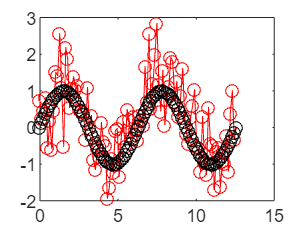

plot(x,y,'-ro')
hold on
plot(x,y_true,'-ko')

Let's start with simplest filtering technique

close all
y_cleaned=movmean(y,20)

y_cleaned =     0.4692    0.6590    0.6959    0.6030    0.7156    0.7930    0.7770    0.7932    0.8257    0.8362    0.8521    0.8395    0.8492    0.8467    0.7894    0.8707    0.8600    0.9057    0.8386    0.7052    0.6058    0.4382    0.3893    0.3963    0.2629    0.0724   -0.0365   -0.1315   -0.2626   -0.3184   -0.3778   -0.4692   -0.5042   -0.5163   -0.5252   -0.5550   -0.5435   -0.5736   -0.5145   -0.4595   -0.4483   -0.3929   -0.3883   -0.3669   -0.2591   -0.1276    0.0822    0.1510    0.2736    0.3776


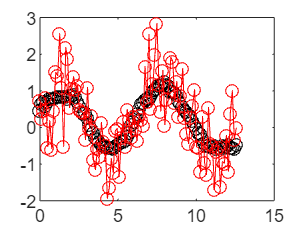

plot(x,y_cleaned,'-ko')
hold on
plot(x,y,'-ro')

size(y)

ans =      1   100


Let's try another form of noisy signals

clc; clear; close all;
x=linspace(0,pi/2,300);
y_true=sin(2*pi*x)

y_true =          0    0.0330    0.0660    0.0989    0.1317    0.1643    0.1968    0.2290    0.2610    0.2927    0.3241    0.3552    0.3858    0.4161    0.4458    0.4751    0.5039    0.5322    0.5598    0.5869    0.6133    0.6390    0.6640    0.6883    0.7119    0.7347    0.7567    0.7778    0.7982    0.8176    0.8362    0.8538    0.8705    0.8863    0.9011    0.9149    0.9277    0.9396    0.9503    0.9601    0.9688    0.9765    0.9830    0.9886    0.9930    0.9964    0.9986    0.9998    0.9999    0.9989


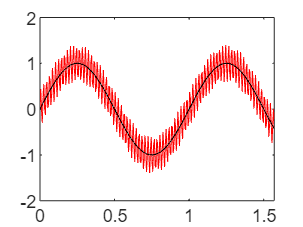

y=sin(2*pi*x)+0.4*sin(2*pi*50*x);
plot(x,y,'-r')
hold on
plot(x,y_true,'-k')

Let's try to clean that with low bass filter

close all;
fs=1/(x(2)-x(1))

fs = 190.3493

y_clean=lowpass(y,40,fs)

y_clean =     0.1598    0.1108    0.0239    0.0396    0.1434    0.2097    0.1990    0.1950    0.2520    0.3177    0.3363    0.3377    0.3727    0.4277    0.4585    0.4681    0.4926    0.5359    0.5694    0.5855    0.6055    0.6388    0.6700    0.6893    0.7075    0.7332    0.7597    0.7793    0.7961    0.8162    0.8373    0.8548    0.8698    0.8854    0.9014    0.9154    0.9275    0.9391    0.9503    0.9602    0.9687    0.9762    0.9830    0.9886    0.9928    0.9961    0.9986    0.9998    0.9997    0.9987


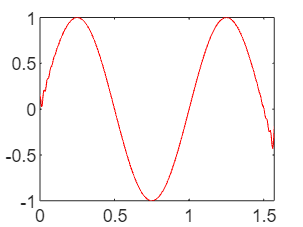

plot(x,y_clean,'r')

hold on
plot(x,y,'k')

But what if we don't know the noise frequency?

clc; clear; close all;
rand_freq=10+rand(1)*100;
x=linspace(0,pi/2,300);
y_true=sin(2*pi*x)

y_true =          0    0.0330    0.0660    0.0989    0.1317    0.1643    0.1968    0.2290    0.2610    0.2927    0.3241    0.3552    0.3858    0.4161    0.4458    0.4751    0.5039    0.5322    0.5598    0.5869    0.6133    0.6390    0.6640    0.6883    0.7119    0.7347    0.7567    0.7778    0.7982    0.8176    0.8362    0.8538    0.8705    0.8863    0.9011    0.9149    0.9277    0.9396    0.9503    0.9601    0.9688    0.9765    0.9830    0.9886    0.9930    0.9964    0.9986    0.9998    0.9999    0.9989


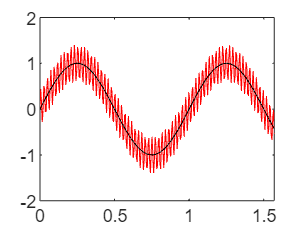

y=sin(2*pi*x)+0.4*sin(2*pi*rand_freq*x);
plot(x,y,'-r')
hold on
plot(x,y_true,'-k')

We need to apply fft()

close all
fs=1/(x(2)-x(1))

fs = 190.3493

N = length(y);
f = (0:N-1)*(fs/N);
Y=fft(y)

Y =   57.8092 + 0.0000i  96.3533 +14.8017i -93.0990 -28.9543i -21.1907 -10.0924i  -9.8982 - 6.4761i  -5.6963 - 4.8484i  -3.6248 - 3.8977i  -2.4395 - 3.2657i  -1.6941 - 2.8114i  -1.1932 - 2.4671i  -0.8397 - 2.1962i  -0.5806 - 1.9768i  -0.3846 - 1.7950i  -0.2326 - 1.6414i  -0.1122 - 1.5098i  -0.0150 - 1.3955i   0.0646 - 1.2950i   0.1309 - 1.2058i   0.1868 - 1.1260i   0.2344 - 1.0540i   0.2754 - 0.9886i   0.3111 - 0.9287i   0.3425 - 0.8736i   0.3703 - 0.8227i   0.3953 - 0.7753i   0.4177 - 0.7309i   0.4382 - 0.6893i   0.4570 - 0.6500i   0.4744 - 0.6128i   0.4906 - 0.5774i   0.5059 - 0.5436i   0.5203 - 0.5111i   0.5341 - 0.4798i   0.5474 - 0.4495i   0.5604 - 0.4202i   0.5730 - 0.3915i   0.5855 - 0.3635i   0.5979 - 0.3359i   0.6103 - 0.3087i   0.6228 - 0.2817i   0.6355 - 0.2548i   0.6485 - 0.2279i   0.6619 - 0.2009i   0.6758 - 0.1736i   0.6903 - 0.1458i   0.7055 - 0.1175i   0.7216 - 0.0885i   0.7387 - 0.0585i   0.7571 - 0.0273i   0.7768 + 0.0053i


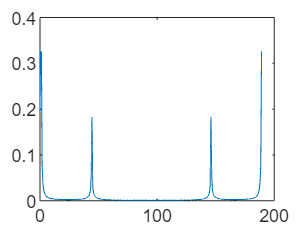

plot(f,abs(Y)/N)

Notice the symmetry issue, let's solve it

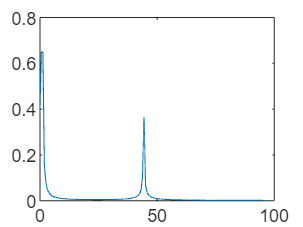

halfPoint = floor(N/2) + 1;
plot(f(1:halfPoint), abs(Y(1:halfPoint))/N * 2)